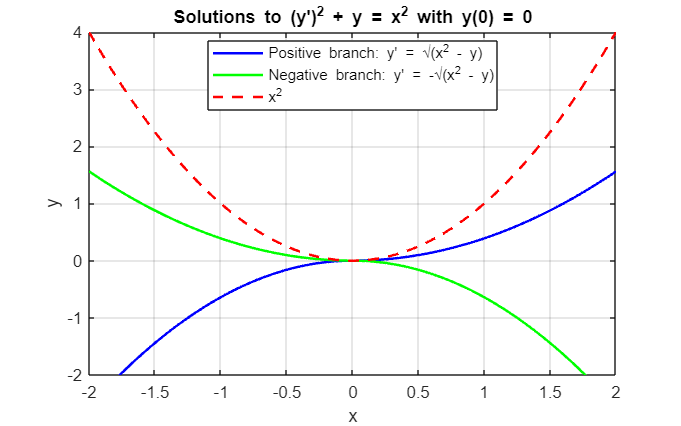

% Clear previous data
clear all;
clc;

% Define the ODE functions
% Positive branch: y' = sqrt(x^2 - y)
ode_positive = @(x, y) sqrt(x^2 - y);
% Negative branch: y' = -sqrt(x^2 - y)
ode_negative = @(x, y) -sqrt(x^2 - y);

% Define x ranges
x_pos = 0:0.01:2;  % Positive x from 0 to 2
x_neg = 0:-0.01:-2; % Negative x from 0 to -2 (reversed for integration)

% Initial condition
y0 = 0;

% Solve for positive branch
[x_pos_sol_pos, y_pos_sol_pos] = ode45(ode_positive, x_pos, y0); % Positive x
[x_neg_sol_pos, y_neg_sol_pos] = ode45(ode_positive, x_neg, y0); % Negative x

% Solve for negative branch
[x_pos_sol_neg, y_pos_sol_neg] = ode45(ode_negative, x_pos, y0); % Positive x
[x_neg_sol_neg, y_neg_sol_neg] = ode45(ode_negative, x_neg, y0); % Negative x

% Combine solutions (flip negative x solutions for plotting)
x_full = [flip(x_neg_sol_pos); x_pos_sol_pos];
y_full_positive = [flip(y_neg_sol_pos); y_pos_sol_pos];
x_full_neg = [flip(x_neg_sol_neg); x_pos_sol_neg];
y_full_negative = [flip(y_neg_sol_neg); y_pos_sol_neg];

% Plot the solutions
figure('Position', [100, 100, 800, 500]);
plot(x_full, y_full_positive, 'b-', 'LineWidth', 1.5, 'DisplayName', "Positive branch: y' = \surd(x^2 - y)");
hold on;
plot(x_full_neg, y_full_negative, 'g-', 'LineWidth', 1.5, 'DisplayName', "Negative branch: y' = -\surd(x^2 - y)");
plot(x_full, x_full.^2, 'r--', 'LineWidth', 1.5, 'DisplayName', 'x^2');
grid on;
xlabel('x');
ylabel('y');
title("Solutions to (y')^2 + y = x^2 with y(0) = 0");
legend('Location', 'best');
axis([-2 2 -2 4]); % Set limits to show positive and negative y
hold off;


% Verify initial condition and equation
disp('Positive branch:');

Positive branch:


disp(['y(0) = ', num2str(y_pos_sol_pos(1))]);

y(0) = 0


dy0_pos = (y_pos_sol_pos(2) - y_pos_sol_pos(1)) / (x_pos_sol_pos(2) - x_pos_sol_pos(1));
disp(['Approximate y''(0) = ', num2str(dy0_pos)]);

Approximate y'(0) = 0.0040364


disp(['Check at x=0: ', num2str(dy0_pos^2 + y_pos_sol_pos(1)), ' vs 0']);

Check at x=0: 1.6292e-05 vs 0



disp('Negative branch:');

Negative branch:


disp(['y(0) = ', num2str(y_pos_sol_neg(1))]);

y(0) = 0


dy0_neg = (y_pos_sol_neg(2) - y_pos_sol_neg(1)) / (x_pos_sol_neg(2) - x_pos_sol_neg(1));
disp(['Approximate y''(0) = ', num2str(dy0_neg)]);

Approximate y'(0) = -0.0063837


disp(['Check at x=0: ', num2str(dy0_neg^2 + y_pos_sol_neg(1)), ' vs 0']);

Check at x=0: 4.0751e-05 vs 0



% Check at x = 1
idx_pos = find(abs(x_pos_sol_pos - 1) < 0.01, 1);
idx_neg = find(abs(x_pos_sol_neg - 1) < 0.01, 1);

disp('Positive branch at x ≈ 1:');

Positive branch at x ≈ 1:


y1_pos = y_pos_sol_pos(idx_pos);
x1_pos = x_pos_sol_pos(idx_pos);
dy1_pos = (y_pos_sol_pos(idx_pos+1) - y_pos_sol_pos(idx_pos-1)) / ...
          (x_pos_sol_pos(idx_pos+1) - x_pos_sol_pos(idx_pos-1));
disp(['y = ', num2str(y1_pos), ', y'' = ', num2str(dy1_pos)]);

y = 0.39039, y' = 0.78078


disp(['(y'')^2 + y = ', num2str(dy1_pos^2 + y1_pos), ' vs x^2 = ', num2str(x1_pos^2)]);

(y')^2 + y = 1 vs x^2 = 1



disp('Negative branch at x ≈ 1:');

Negative branch at x ≈ 1:


y1_neg = y_pos_sol_neg(idx_neg);
x1_neg = x_pos_sol_neg(idx_neg);
dy1_neg = (y_pos_sol_neg(idx_neg+1) - y_pos_sol_neg(idx_neg-1)) / ...
          (x_pos_sol_neg(idx_neg+1) - x_pos_sol_neg(idx_neg-1));
disp(['y = ', num2str(y1_neg), ', y'' = ', num2str(dy1_neg)]);

y = -0.64039, y' = -1.2808


disp(['(y'')^2 + y = ', num2str(dy1_neg^2 + y1_neg), ' vs x^2 = ', num2str(x1_neg^2)]);

(y')^2 + y = 1 vs x^2 = 1
